% Script to extract and analyze data acquired with the ActiWheel actigraphy wheel system.
% Written by Riccardo Avvisati in December 2019.
% The input is a single binary file from ActiWheel that needs to be in the current folder.
% The file needs to be of at least 7 consecutive days (from 8PM on day1 to 8PM of day8).
% The script converts the binary file produced by the ActiWheel into ASCII and outputs an actograph
% along with average speed per day (and a few overall distributions of speed per bout, bout duration etc.).


%Extract data from file and convert them from binary format
clear all;

file = dir('*.dat');
filename = file.name;
fileID = fopen(filename);
matlabFilename = [filename(1:end-4), '.mat'];
fileSize = (file.bytes)/10;
potVector = fread(fileID, fileSize,'uint16', 8);     %read the binary file in a uint16 vector
fseek(fileID, 2, 'bof');
timeVector = fread(fileID, fileSize, 'uint32', 6);
fclose(fileID);

%Extract running bouts data from the continuous potentiometer signal
wheelDiam = 12;
runningBouts = [];                      %prepare a matrix to store the running bouts

halfTurn = 0;                           %initialize this variable at 0, we'll use it to count wheel half-turns
idleCounter = 0;                        %this counter will be reset to zero whenever an half-turn is detected
idleSeconds = 5;                        %amount of time to pass without an half-turn to "close" the running bout
boutOpen = false;
turnEstablished = false;
turnClock = -1;
lastTurnClock = -1;

tempEndTime = 0;                        %support variable
tempEndIdx = 0;                         %support variable

if isfile(matlabFilename)
    load(matlabFilename);
else
    
    for i=1:length(potVector)                                           %going through the entire potentiometer vector
        if ~boutOpen                                                    %if a running bout has not started yet
            if (potVector(i) >= 200) && (potVector(i) <=220)            %look for a potentiometer value around 210 (arbitrary)
                boutOpen = true;                                        %now the bout is open
                boutStartTime = timeVector(i);                          %take unix timestamp of start of bout
                boutStartIdx = i;                                       %take row index of start of bout
                segment210 = true;                                      %we have gone through "segment 210"
            elseif (potVector(i) >= 740) && (potVector(i) <=760)        %at the same time, look for a potentiometer value around 750 (180 degrees away, opposite point on wheel)
                boutOpen = true;                                        %same as above
                boutStartTime = timeVector(i);
                boutStartIdx = i;
                segment210 = false;                                     %except now we have passed segment 750, so this flag is false
            end
        else                                                            %if instead a bout is already open
            if segment210                                               %and we've been through the segment 210
                if (potVector(i) >= 740) && (potVector(i) <=760)        %look for when we go through the segment 750!
                    halfTurn = halfTurn + 1;                            %if we go through it, we made half a turn! increment the counter
                    idleCounter = 0;                                    %reset the idleCounter
                    tempEndTime = timeVector(i);                        %keep the timestamp so that if this is the last half turn of the bout we'll use it as the end of bout timestamp
                    tempEndIdx = i;                                     %keep the row index as well, it will be used to calculate speed (1 row index increment = 10 ms)
                    segment210 = false;                                 %we have gone through segment 750 so this is now false
                end
                if (potVector(i) >= 470) && (potVector(i) <= 490)
                    lastTurnClock = turnClock;
                    turnClock = true;
                    turnEstablished = true;
                elseif (potVector(i) >= 1010) && (potVector(i) <= 1020)
                    lastTurnClock = turnClock;
                    turnClock = false;
                    turnEstablished = true;
                end
            else                                                        %instead, if we've been through segment 750
                if (potVector(i) >= 200) && (potVector(i) <=220)        %look for when we go through segment 210
                    halfTurn = halfTurn + 1;                            %same as above
                    idleCounter = 0;
                    tempEndTime = timeVector(i);
                    tempEndIdx = i;
                    segment210 = true;
                end
                if (potVector(i) >= 470) && (potVector(i) <= 490)
                    lastTurnClock = turnClock;
                    turnClock = false;
                    turnEstablished = true;
                elseif (potVector(i) >= 1010) && (potVector(i) <= 1020)
                    lastTurnClock = turnClock;
                    turnClock = true;
                    turnEstablished = true;
                end
            end
            idleCounter = idleCounter + 1;                              %increment idleCounter so that we can keep track of how long it passed since last half turn
        end                                                             %it is incremented
        if (idleCounter >= idleSeconds*100) || (turnEstablished && (turnClock ~= lastTurnClock) && lastTurnClock ~= -1)                              %if the idleCounter is higher than a threshold
            boutEndTime = tempEndTime;                                  %now the last end time is the actual end time of the running bout
            boutEndIdx = tempEndIdx;                                    %same for the row index
            boutSpeed = ((halfTurn/2)*(wheelDiam*pi))/((boutEndIdx-boutStartIdx)*0.01);
            if (halfTurn > 0) && (boutSpeed < 70)                       %only include the bout if there is at least 1 half a turn and speed is not too high (if the pot stops in its "dead" position the signal can artefactually fluctuate quite fast)
                runningBouts = [runningBouts; boutStartTime, boutEndTime, halfTurn/2, boutSpeed, lastTurnClock];
            end
            boutOpen = false;                                           %close the bout
            turnEstablished = false;
            turnClock = -1;
            lastTurnClock = -1;
            halfTurn = 0;
            idleCounter = 0;
        end
    end
    save(matlabFilename, 'runningBouts');
end

%Organize data in days and bin the data to generate actograph
binSize = 600;   %bin size in seconds

for k=1:size(timeVector, 1)
    if rem((timeVector(k)-72000), 86400) == 0   %go through timestamps to find the first to be 8:00 PM of any day (72000 is 20 hours in seconds, 86400 is 1 day in seconds)
        sessionStartTime = timeVector(k);        %if a timestamp - 20 hours is divisible for the number of seconds in a day, it means it's 8 AM of one day
        break;
    end
end
dayStartTime = sessionStartTime;                    %the session start time is also the start time of the first day
dayEndTime = dayStartTime + 86400;                  %add 1 day in seconds to find the end time of the day
binVecMat = [];                                     %initialize arrays to populate
dayAvgSpeed = [];
dayAvgSpeedClock = [];
dayAvgSpeedCounterClock = [];
dayMaxSpeed = [];
dayMaxSpeedClock = [];
dayMaxSpeedCounterClock = [];
dayAvgBoutDur = [];
dayAvgBoutDurClock = [];
dayAvgBoutDurCounterClock = [];
dayWeightedSpeed = [];
dayWeightedSpeedClock = [];
dayWeightedSpeedCounterClock = [];
dayTotalDistance = [];
percClockDistance = [];

day = 0;
if (timeVector(end)-timeVector(1)) >= 86400         %check that the length of the entire file is at least 1 day
    while dayEndTime <= timeVector(end)             %as long as the dayEndTime is lower than the last timestamp present in the full file...
        day = day + 1;                              %increment day index
        dayEndTime = dayStartTime + 86400;          %add 1 day to the day start time to obtain the end of day time
        dayRunningBouts = [];                       %initialize an array to store the running bouts for the current day
        
        for j=1:size(runningBouts, 1)               %go through all the running bouts
            if (runningBouts(j, 1) >= dayStartTime) && (runningBouts(j, 1) <= dayEndTime) %if the start timestamp is within the start and end of the day, it's in that day!
                dayRunningBouts = [dayRunningBouts; runningBouts(j,:)];                   %add the bout to the list of bouts for current day
            end
        end
        
        if ~isempty(dayRunningBouts)
            dayRunningBoutsIncluded = dayRunningBouts(dayRunningBouts(:,3)>=5, :);
        else
            dayRunningBouts = [NaN, NaN, NaN, NaN, NaN];
            dayRunningBoutsIncluded = [NaN, NaN, NaN, NaN, NaN];
        end
        
        dayRunningBoutsCell{day} = dayRunningBoutsIncluded;                     %put the matrix of included bouts for the current day in the cell array
        
        dayRunningBoutsIncludedClock = dayRunningBoutsIncluded(dayRunningBoutsIncluded(:,5)==1,:);
        dayRunningBoutsIncludedCounterClock = dayRunningBoutsIncluded(dayRunningBoutsIncluded(:,5)==0,:);
        
        if ~isempty(dayRunningBoutsIncluded)
            dayAvgSpeed = [dayAvgSpeed; mean(dayRunningBoutsIncluded(:,4))];    %build a vector with average speed (1 row = 1 day)
            dayMaxSpeed = [dayMaxSpeed; max(dayRunningBoutsIncluded(:,4))];     %build a vector with maximum speed (1 row = 1 day)
            dayAvgBoutDur = [dayAvgBoutDur; mean(dayRunningBoutsIncluded(:,2)-dayRunningBoutsIncluded(:,1))];
            dayWeightedSpeed = [dayWeightedSpeed; (sum(dayRunningBoutsIncluded(:,4).*dayRunningBoutsIncluded(:,3)))/sum(dayRunningBoutsIncluded(:,3))];
            
            dayTotalDistance = [dayTotalDistance; (sum(dayRunningBoutsIncluded(:,3))*wheelDiam*pi)/100];
            percClockDistance = [percClockDistance; sum(dayRunningBoutsIncludedClock(:,3))/sum(dayRunningBoutsIncluded(:,3))*100];
            
            if ~isempty(dayRunningBoutsIncludedClock)
                dayAvgSpeedClock = [dayAvgSpeedClock; mean(dayRunningBoutsIncludedClock(:,4))];
                dayMaxSpeedClock = [dayMaxSpeedClock; max(dayRunningBoutsIncludedClock(:,4))];
                dayAvgBoutDurClock = [dayAvgBoutDurClock; mean(dayRunningBoutsIncludedClock(:,2)-dayRunningBoutsIncludedClock(:,1))];
                dayWeightedSpeedClock = [dayWeightedSpeedClock; (sum(dayRunningBoutsIncludedClock(:,4).*dayRunningBoutsIncludedClock(:,3)))/sum(dayRunningBoutsIncludedClock(:,3))];
            else
                dayAvgSpeedClock = [dayAvgSpeedClock; NaN];
                dayMaxSpeedClock = [dayMaxSpeedClock; NaN];
                dayAvgBoutDurClock = [dayAvgBoutDurClock; NaN];
                dayWeightedSpeedClock = [dayWeightedSpeedClock; NaN];
            end
            
            if ~isempty(dayRunningBoutsIncludedCounterClock)
                dayAvgSpeedCounterClock = [dayAvgSpeedCounterClock; mean(dayRunningBoutsIncludedCounterClock(:,4))];
                dayMaxSpeedCounterClock = [dayMaxSpeedCounterClock; max(dayRunningBoutsIncludedCounterClock(:,4))];
                dayAvgBoutDurCounterClock = [dayAvgBoutDurCounterClock; mean(dayRunningBoutsIncludedCounterClock(:,2)-dayRunningBoutsIncludedCounterClock(:,1))];
                dayWeightedSpeedCounterClock = [dayWeightedSpeedCounterClock; (sum(dayRunningBoutsIncludedCounterClock(:,4).*dayRunningBoutsIncludedCounterClock(:,3)))/sum(dayRunningBoutsIncludedCounterClock(:,3))];
            else
                dayAvgSpeedCounterClock = [dayAvgSpeedCounterClock; NaN];
                dayMaxSpeedCounterClock = [dayMaxSpeedCounterClock; NaN];
                dayAvgBoutDurCounterClock = [dayAvgBoutDurCounterClock; NaN];
                dayWeightedSpeedCounterClock = [dayWeightedSpeedCounterClock; NaN];
            end
        else
            dayRunningBoutsIncluded = [NaN, NaN, NaN, NaN, NaN];
            dayAvgSpeed = [dayAvgSpeed; NaN];
            dayMaxSpeed = [dayMaxSpeed; NaN];
            dayWeightedSpeed = [dayWeightedSpeed; NaN];
            dayAvgBoutDur = [dayAvgBoutDur; NaN];
            
            dayTotalDistance = [dayTotalDistance; 0];
            percClockDistance = [percClockDistance; NaN];
            
            dayAvgSpeedClock = [dayAvgSpeedClock; NaN];
            dayMaxSpeedClock = [dayMaxSpeedClock; NaN];
            dayWeightedSpeedClock = [dayWeightedSpeedClock; NaN];
            dayAvgBoutDurClock = [dayAvgBoutDurClock; NaN];
            
            dayAvgSpeedCounterClock = [dayAvgSpeedCounterClock; NaN];
            dayMaxSpeedCounterClock = [dayMaxSpeedCounterClock; NaN];
            dayWeightedSpeedCounterClock = [dayWeightedSpeedCounterClock; NaN];
            dayAvgBoutDurCounterClock = [dayAvgBoutDurCounterClock; NaN];
        end
        
        binVector = [];
        for binEdge=dayStartTime:binSize:dayEndTime                                     %bin the data in 10 minutes bin for the actograph
            binRunningBouts = dayRunningBouts(dayRunningBouts(:,1)>= binEdge & dayRunningBouts(:,1) < binEdge+binSize-1 ,:);
            binVector = [binVector, sum(binRunningBouts(:,3))*wheelDiam*pi/100];
        end
        binVecMat = [binVecMat; binVector];
        dayStartTime = dayStartTime + 86400;     %increase the day start time of 1 day for the next day
    end
end

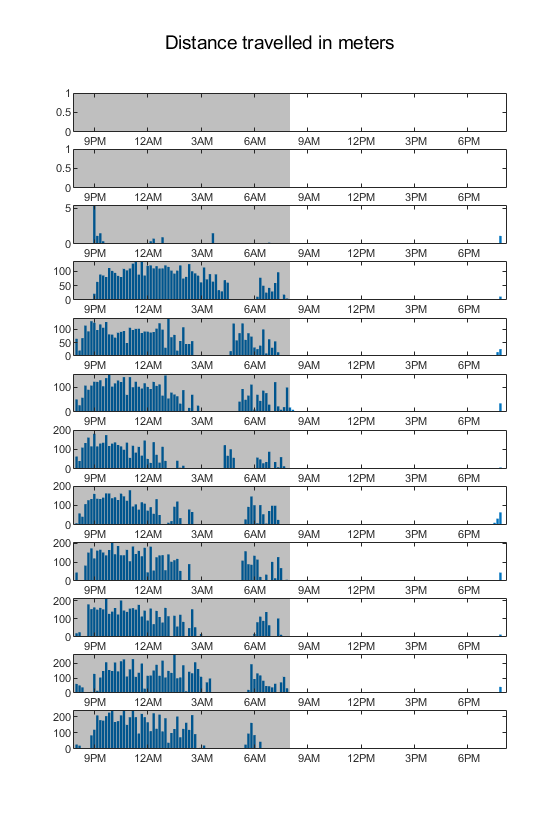

%plot actigraph
dateVector = sessionStartTime:binSize:(sessionStartTime + 86400);
d = datenum(datetime(dateVector, 'ConvertFrom', 'epochtime'));
figure

set(gcf, 'position', [10, 10, 560, 70*day])
for n=1:day
    subplot(size(binVecMat, 1), 1, n);
    bar(d, binVecMat(n,:), 'EdgeColor', 'none')
    xl = xlim;
    yl = ylim;
    patch([xl(1) mean(xl) mean(xl) xl(1)], [0 0 yl(2) yl(2)], 'black', 'FaceAlpha', 0.25, 'EdgeColor', 'none')
    datetick('x', 'HHPM', 'keeplimits');
end
suptitle("Distance travelled in meters");

%plot motor performances and write tables to .xlsx file

excelfilename = [filename(1:end-4), '.xlsx'];

AvgSpeedTable = table(dayAvgSpeed, dayAvgSpeedClock, dayAvgSpeedCounterClock);
AvgSpeedTable.Properties.VariableNames(1:3) = {'Overall', 'Clockwise', 'Counterclockwise'};
writetable(AvgSpeedTable, excelfilename, 'Sheet', 'Average Speed (cm-s)');


MaxSpeedTable = table(dayMaxSpeed, dayMaxSpeedClock, dayMaxSpeedCounterClock);
MaxSpeedTable.Properties.VariableNames(1:3) = {'Overall', 'Clockwise', 'Counterclockwise'};
writetable(MaxSpeedTable, excelfilename, 'Sheet', 'Max Speed (cm-s)');


WeightedSpeedTable = table(dayWeightedSpeed, dayWeightedSpeedClock, dayWeightedSpeedCounterClock);
WeightedSpeedTable.Properties.VariableNames(1:3) = {'Overall', 'Clockwise', 'Counterclockwise'};
writetable(WeightedSpeedTable, excelfilename, 'Sheet', 'Weighted Speed (cm-s)');


AvgBoutDurTable = table(dayAvgBoutDur, dayAvgBoutDurClock, dayAvgBoutDurCounterClock);
AvgBoutDurTable.Properties.VariableNames(1:3) = {'Overall', 'Clockwise', 'Counterclockwise'};
writetable(AvgBoutDurTable, excelfilename, 'Sheet', 'Avg Bout Duration (s)');

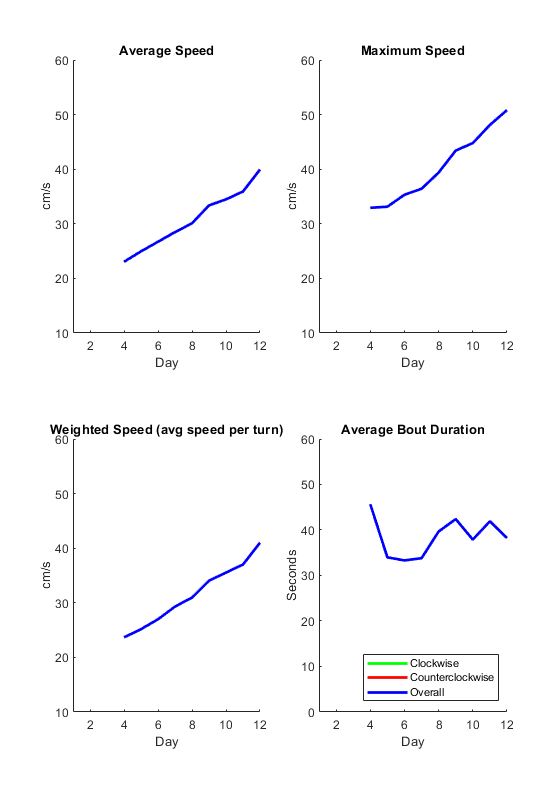


figure
set(gcf, 'position', [10, 10, 560, 800]);
subplot(2,2,1);
hold on
plot(dayAvgSpeedClock, 'green', 'LineWidth', 2)
plot(dayAvgSpeedCounterClock, 'red', 'LineWidth', 2)
plot(dayAvgSpeed, 'blue', 'LineWidth', 2)
title("Average Speed");
set(gca, 'box', 'off');
ylim([10 60]);
xlim([1 length(dayAvgSpeed)]);
ylabel("cm/s");
xlabel("Day");
%legend('Clockwise', 'Counterclockwise', 'Overall', 'Location', 'southeast')
hold off

subplot(2,2,2);
hold on
plot(dayMaxSpeedClock, 'green', 'LineWidth', 2)
plot(dayMaxSpeedCounterClock, 'red', 'LineWidth', 2)
plot(dayMaxSpeed, 'blue', 'LineWidth', 2)
title("Maximum Speed");
set(gca, 'box', 'off');
ylim([10 60]);
xlim([1 length(dayAvgSpeed)]);
ylabel("cm/s");
xlabel("Day");
%legend('Clockwise', 'Counterclockwise', 'Overall', 'Location', 'southeast')
hold off

subplot(2,2,3);
hold on
plot(dayWeightedSpeedClock, 'green', 'LineWidth', 2)
plot(dayWeightedSpeedCounterClock, 'red', 'LineWidth', 2)
plot(dayWeightedSpeed, 'blue', 'LineWidth', 2)
title("Weighted Speed (avg speed per turn)");
set(gca, 'box', 'off');
ylim([10 60]);
xlim([1 length(dayAvgSpeed)]);
ylabel("cm/s");
xlabel("Day");
%legend('Clockwise', 'Counterclockwise', 'Overall', 'Location', 'southeast')
hold off


subplot(2,2,4);
hold on
plot(dayAvgBoutDurClock, 'green', 'LineWidth', 2)
plot(dayAvgBoutDurCounterClock, 'red', 'LineWidth', 2)
plot(dayAvgBoutDur, 'blue', 'LineWidth', 2)
title("Average Bout Duration");
set(gca, 'box', 'off');
ylim([0 60]);
xlim([1 length(dayAvgSpeed)]);
ylabel("Seconds");
xlabel("Day");
legend('Clockwise', 'Counterclockwise', 'Overall', 'Location', 'southeast')
hold off

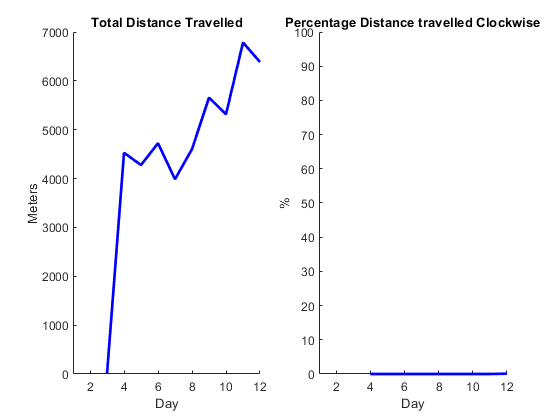


figure
subplot(1,2,1)
plot(dayTotalDistance, 'blue', 'LineWidth', 2)
title("Total Distance Travelled");
set(gca, 'box', 'off');
xlim([1 length(dayAvgSpeed)]);
xlabel("Day");
ylabel("Meters");

subplot(1,2,2)
plot(percClockDistance, 'blue', 'LineWidth', 2)
set(gca, 'box', 'off')
ylim([0 100]);
xlim([1 length(dayAvgSpeed)]);
ylabel("%");
xlabel("Day");
title("Percentage Distance travelled Clockwise")